clear
clc

g = load("gyro.mat");
z = load("gyroZ.mat");

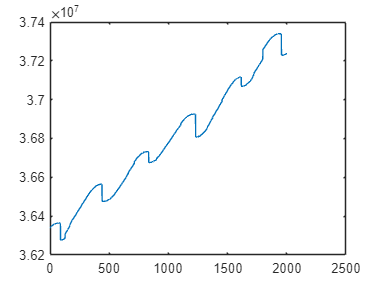



figure
plot(g.gyro.velocity(1500:3500))

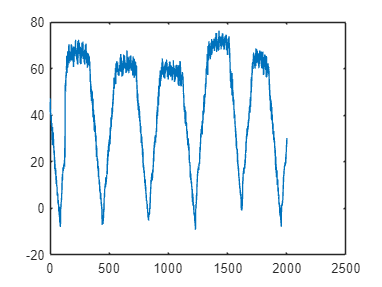



figure
plot(g.gyro.acceleration(1500:3500))

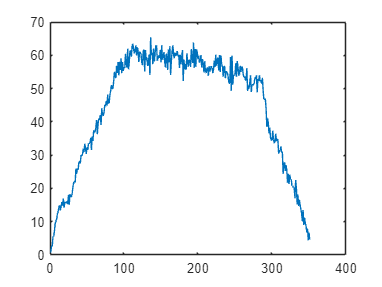


v = g.gyro.acceleration(800:1150);
phi = cumtrapz(v);
figure
plot(v)

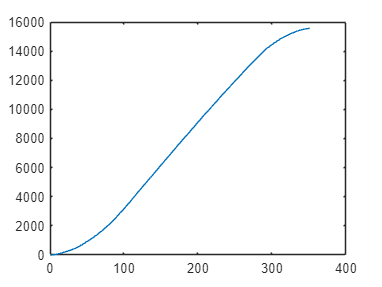


figure
plot(phi)

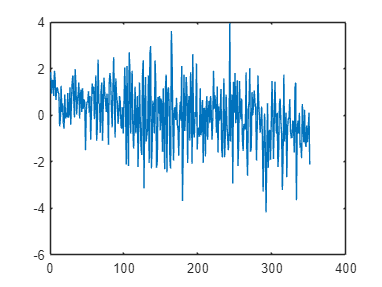

a = gradient(v);
figure
plot(a)

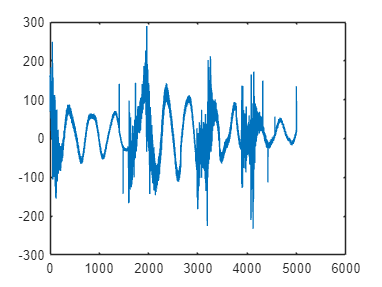

figure
zz = z(50000:55000);
%zz = SmoothCurve(zz, 0.051);
plot(zz)

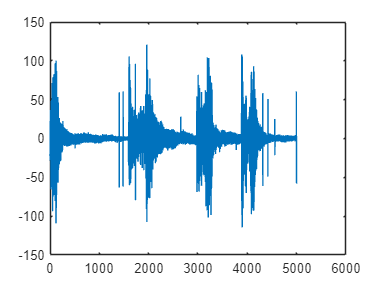


aa = gradient(zz);

figure
plot(aa)